# **Analyze NGS data from Csy4 cleavage in coding sequnece assay: pNaseCsy4 × pRDCrX Large 1 library**

Tested system:

Csy4 expression plasmid: pNaseCsy4.

    origin of replication: p15A

    promoter: tac

    antibiotic resistance: Ampicilin

    Insulator: RiboJ

    RBS: B0034

    CDS: Csy4 wild type from *Pseudomonas aeruginosa (strain UCBPP-PA14)*

Substrate expression plasmid: pRDCrX Large 1 library

    origin of replication: pSC101

    promoter: pBAD

    antibiotic resistance: Kanamycin

    RBS: B0034

    CDS: araC - GG linker - 9 random bp - Csy4 substrate hairpin - 9 random bp - SG linker - GFPmut3

    library size: ~ 10,000

Experimental setup:

Day 0: Scratch the colonies from the agar plate, and dilute in 5 ml fresh LB media, in addition of working concentration of Ampicilin, Kanamycin, 0.2% arabinose, 0.05 mM IPTG, grow in 37 ℃ overnight.

Day 1: Sort the sample by GFP positive or GFP negative gates, by Bio-rad S3e cell sorter in enrichment mode. The sorted samples are refreshed in 5 ml fresh LB media, in addition of working concentration of Ampicilin, Kanamycin, 0.2% arabinose, without IPTG, grow in 37 ℃ overnight.

Day 2: Resort the sorted samples from GFP positive or GFP negative gates, by respective gates, in Single mode, to further purify the sample. The twice sorted samples are refreshed in 6 ml fresh LB media, in addition of working concentration of Ampicilin, Kanamycin, 0.2% arabinose, without IPTG, grow in 37 ℃ overnight.

Day 3: Check the fluorescence of Day 2 samples, to ensure no contamination remained. Extract the plasmid from each sample, and PCR the targeted amplicon by the following primers:

CrX_F: CGTCAAGTTGTCAGGTGG

CrX_R: GTTCTTCTCCTTTACGACCAG (reverse complementary of CTGGTCGTAAAGGAGAAGAAC)

Data is then acquired by NextSeq 500 by Plate-forme de Genomique in Institut Cochin.

# Data extract

## Load in all the samples

Names H119, H133, H135, H153, H155 are Day0, GFP negative Day 1, GFP positive Day1, GFP negative Day 2, GFP negative Day 2 respectively.

#### Set up the filename labels

clear;clc;

Define NGS sample names

Name = {'HG1-H119';'HG3-H133';'HG4-H135';'HG9-H153';'HG10-H155'};

Define experiment names. Gates are 'before sorting','GFP negative','GFP positive','GFP negative sorted twice after overnight growth', and 'GFP positive sorted twice'

Label2 = {'H119','H133','H135','H153','H155'};

Define the minimal substarate of Csy4 that remains constant in the library screening

Core = 'CTGCCGTATAGGCAG';

Define the backbone sequneces amplified by primers. To be noticed, only 8-bp adjacent to the target region of primers are acquired. It is acceptable that the farther sequences are not detected in NGS, or altered due to errors in PCR or NGS.

Note: In many sequence results, sequence "CGAGACCTGTGGT" occurs in the upstream sequence. This is caused by cloning rather than errors that occured in NGS sample preparation, confirming by Sanger sequencing of single colonies isolated from GFP negative pool. CrX_F domain we used differs from this sequence.

CrX_F = 'CAGGTGGT';CrX_R = 'TCTGGTCG';length_F = length(CrX_F);

#### Load the samples

for i = 1:5
    filename = [char(Name(i)),'.x.CTGCCGTATAGGCAG.x.count'];
    savename = [char(Label2(i)),'.mat'];
    % read in all the samples
    [Up,Down,read] = textread(filename,'%s %s %u');

## Preprocess the sequence to filter out the unqualified

Discard the sequences that only has one-side result

    Up = Up(read>0);Down = Down(read>0);read = read(read>0);

The sequencing result should start from the forward primer and end till the reverse primer. By identifying the forward and reverse backbone, we extract the insert sequences.

    startInd = cellfun(@(x) strfind(x,CrX_F),Up,'UniformOutput',false);
    stopInd =cellfun(@(x) strfind(x,CrX_R),Down,'UniformOutput',false);
    index = ~(cellfun(@isempty,startInd) | cellfun(@isempty,stopInd));
    Seq = cellfun(@(a,b,c,d) [a(b(end)+length_F:end),Core,c(1:d(1)-1)],Up(index),startInd(index),Down(index),stopInd(index),'UniformOutput',false); % note multiple domains may be detected
    read = read(index);

#### Filter: The insert sequence should be 33. Shorter or longer inserts are ignored.

    length_seq = cellfun(@length,Seq) == 33;
    Seq = Seq(length_seq);
    read = read(length_seq);

#### Merge the same elements

% merge the same elements
    [Seq,~,c]=unique(Seq);
    Count = accumarray(c,read);
    save(savename,'Seq','Count')
end
clear;clc;

# Data labeling

## Generate the dataset of all sequences detected

First of all, generate a library of all the sequences, and a matrix of their reads in each pool.

% Created 2018/08/13
clear;clc;
% Create an array of all unique sequences detected, and their abundance in each sample 
Label2 = {'H119','H133','H135','H153','H155'};
SeqAll = [];
for i = 1:5
    load([char(Label2(i)),'.mat']);
    SeqAll = [SeqAll;Seq];
end
[SeqAll,ia,ic] = unique(SeqAll);

## Count the read accordingly

#### Add up all the reads

smplsize = numel(SeqAll);
CountAll = zeros(smplsize,5);
for i = 1:5
    load([char(Label2(i)),'.mat']);
    [~,index] = ismember(Seq,SeqAll);
    CountAll(index,i) = Count;
end

## Data labeling

#### Create an arbitrary label

In this assay, GFP negative pools (No.2 and 4) are cleaved pools, and GFP positive pools (No. 3 and 5) are not cleaved.

% an arbitrary way to normalize the frequencies from 4 gates to the same scale
rho_cleaved = (CountAll(:,2)+CountAll(:,4))./(sum(CountAll,2));
rho_noncleaved = (CountAll(:,3)+CountAll(:,5))./(sum(CountAll,2));

Define the cleavability label as the angle in count space -- normalized by the 90 degree to scale 0 to 1.

% if 50:50 probability to be in positive:negative gates, then
% angle(x,y)=45 degree
% cleavability = 1 if RNA is cleaved and detected as GFP negative
Label = angle(1i*rho_cleaved + rho_noncleaved)/angle(1i);
F = (CountAll(:,2)+CountAll(:,4)+1)./(CountAll(:,3)+CountAll(:,5)+1);

#### Save the data as mat file

clearvars -except SeqAll CountAll Sum Label F
save('CrX_All.mat');

# Censor the dataset

clear;clc;close all
load CrX_All.mat

### Censor the data according to the abundance

If the count in the respective pool is lower than 3, the sequence will be discarded.

Count_sorted = max(max(CountAll(:,[2,4]),[],2),max(CountAll(:,[3,5]),[],2));
index = find(Count_sorted>=3);

### Save censored data in a new mat file

SeqAll = SeqAll(index,:);
CountAll = CountAll(index,:);
Label = Label(index);
F = F(index);
clearvars -except SeqAll CountAll Label F
save('CrX_Censored.mat');

# Sequence analysis: transform sequences information into features space

clear;clc;
% load the data
load CrX_Censored.mat
nupackhome ='/Users/qb/Documents/nupack3.1.0/bin/';
Viennahome = '/Users/qb/anaconda2/pkgs/viennarna-2.4.8-py27hd28b015_1/bin/';
Features = CrX_Features_Analysis(SeqAll,nupackhome,Viennahome);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


# Classification random forest model training on sequencing

clear;clc
load('CrX_Censored.mat','SeqAll','Label');

### Discard intermediate phenotypes

Label(Label>=0.7) = 1;
Label(Label<=0.3) = 0;
index = find(abs(Label-0.5) == 0.5);
SeqAll = SeqAll(index,:);
Label = Label(index);

Divide the training/validation/test set

Index1 = find(Label);Index0 = find(Label == 0);
HalfSize = min(numel(Index1),numel(Index0));

rng(2018); % For reproducibility
IndexSample0 = randperm(numel(Index0),HalfSize);% randomly pick part of the dataset for division
[train0,val0,test0] = divideblock(HalfSize,0.7,0.15,0.15);
train0 = Index0(IndexSample0(train0));
val0 = Index0(IndexSample0(val0));
test0 = Index0(IndexSample0(test0));
rng(8102); % For reproducibility
IndexSample1 = randperm(numel(Index1),HalfSize);% randomly pick part of the dataset for division
[train1,val1,test1] = divideblock(HalfSize,0.7,0.15,0.15);
train1 = Index1(IndexSample1(train1));
val1 = Index1(IndexSample1(val1));
test1 = Index1(IndexSample1(test1));

IndexTrain = sort([train0;train1]);
IndexVal = sort([val0;val1]);
IndexTest = sort([test0;test1]);
clearvars train0 val0 test0 train1 val1 test1 IndexSample0 IndexSample1 HalfSize

Train a random forest model on the training set, using sequence information

paroptions = statset('UseParallel',true);
X = cellfun(@nt2int,SeqAll,'UniformOutput',false);
X = double(cell2mat(X));
X = X(:,[1:9,end-8:end]); 
mdl = TreeBagger(50,X(IndexTrain,:),Label(IndexTrain),...
    'Method','classification',...
    'OOBPrediction','On',...
    'Options',paroptions);

Plot the out-of-bag classification error

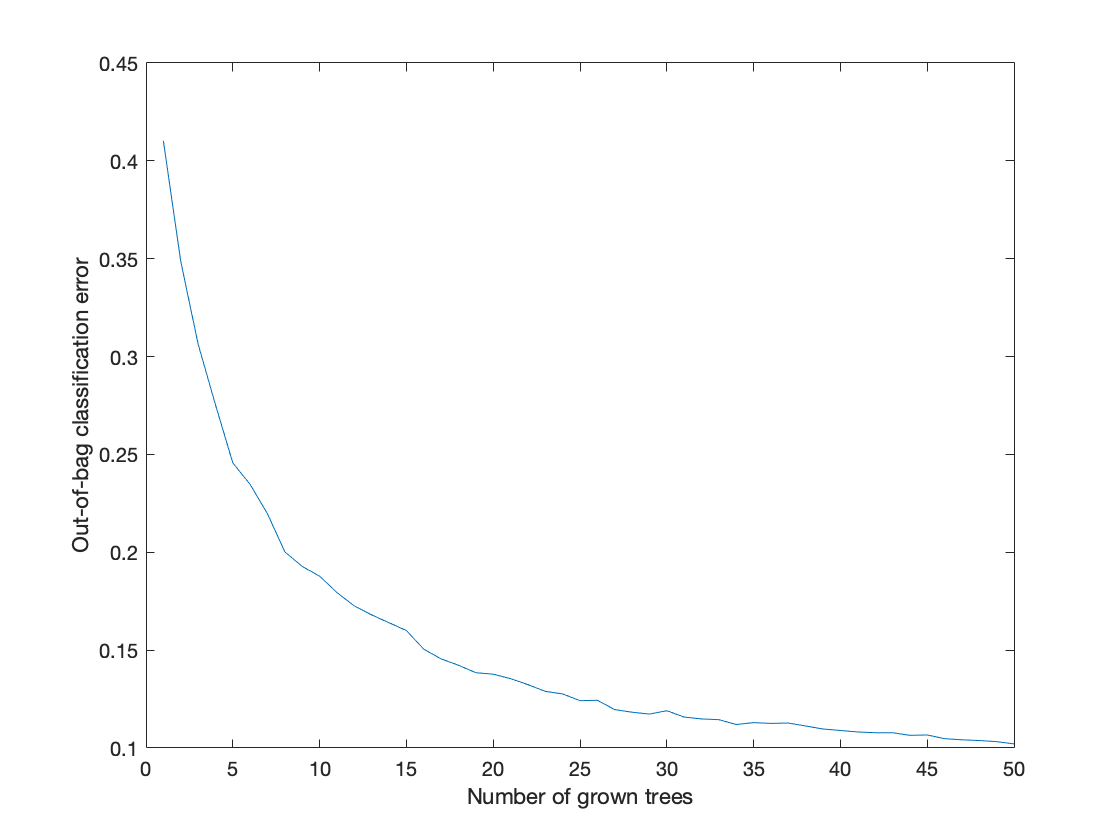

figure;
oobErrorBaggedEnsemble = oobError(mdl);
plot(oobErrorBaggedEnsemble)
xlabel('Number of grown trees');
ylabel('Out-of-bag classification error');

Plot ROC curve

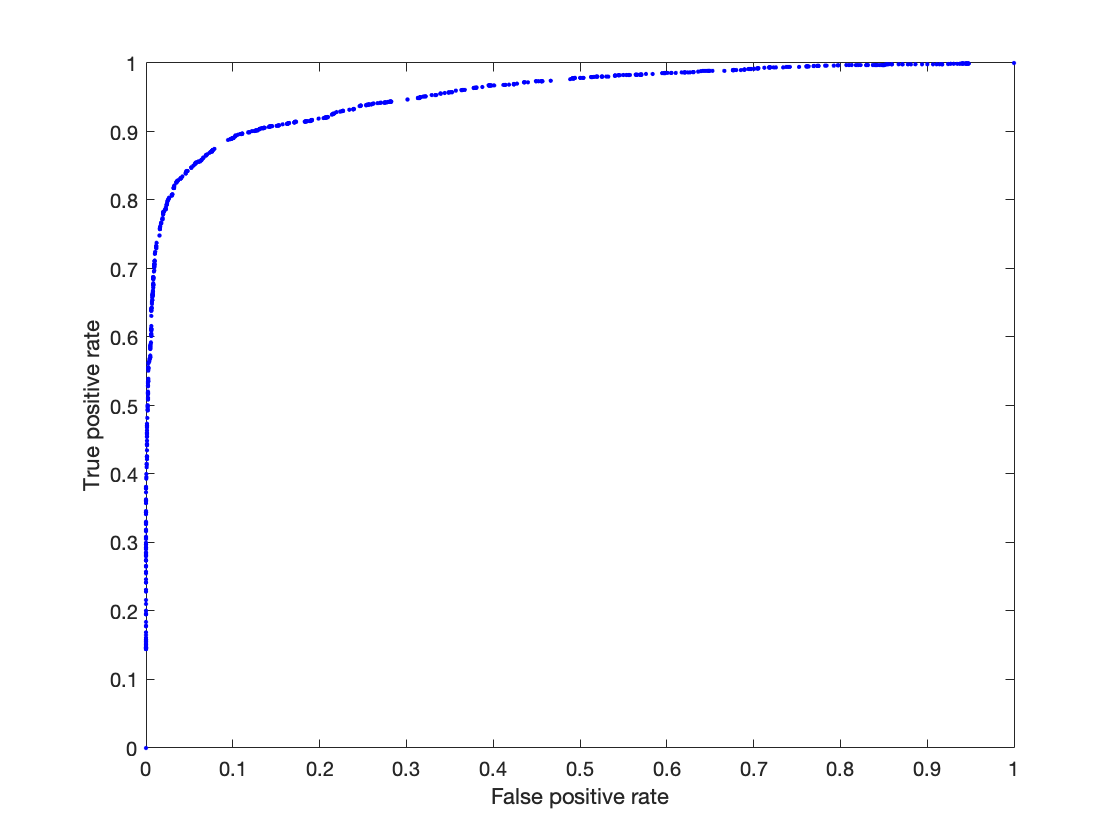

gPosition_all = find(strcmp('1',mdl.ClassNames))';
[~,Sfit] = oobPredict(mdl);
[fpr,tpr] = perfcurve(mdl.Y,Sfit(:,gPosition_all),'1');
figure
plot(fpr,tpr,'b.');
xlabel('False positive rate');ylabel('True positive rate');

Cross-validation on the validation set

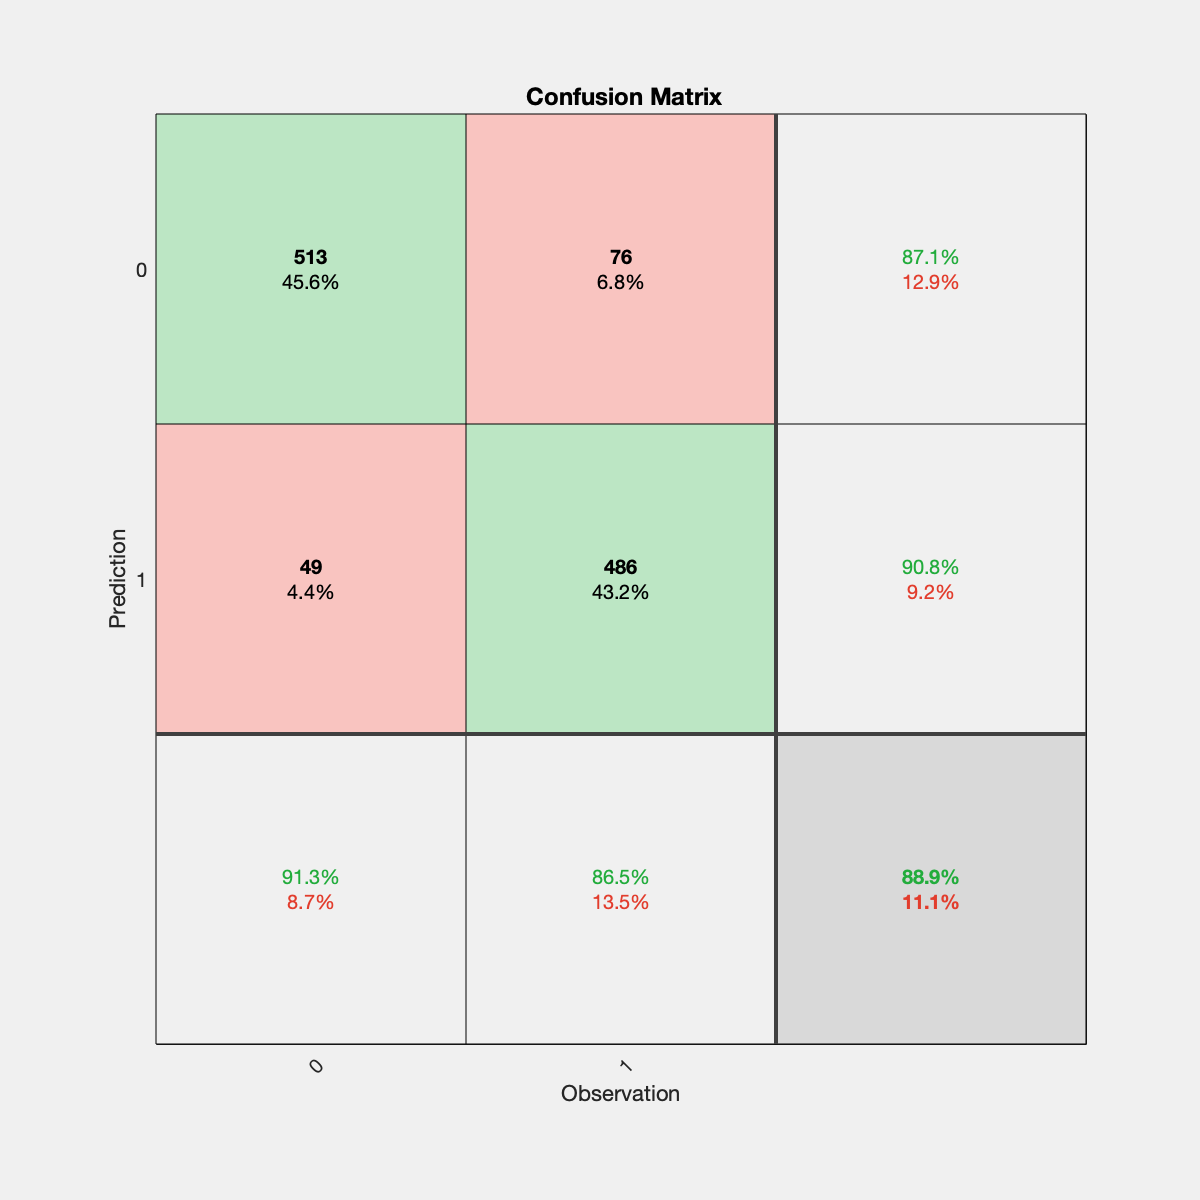

[Countfit,~,~] = predict(mdl,X(IndexVal,:));
Prediction = cellfun(@str2num,Countfit);
Observation = Label(IndexVal);
plotconfusion(categorical(Observation),categorical(Prediction));
xlabel('Observation');ylabel('Prediction')